We set up a test problem with velocity $c=2$ and periodic end conditions. 

[x,Dx] = diffper(200,[0 1]);
c = 2;  
uinit = exp(-80*(x-0.5).^2);

For this problem we use `ode113`, which uses a combination of explicit multistep methods. 

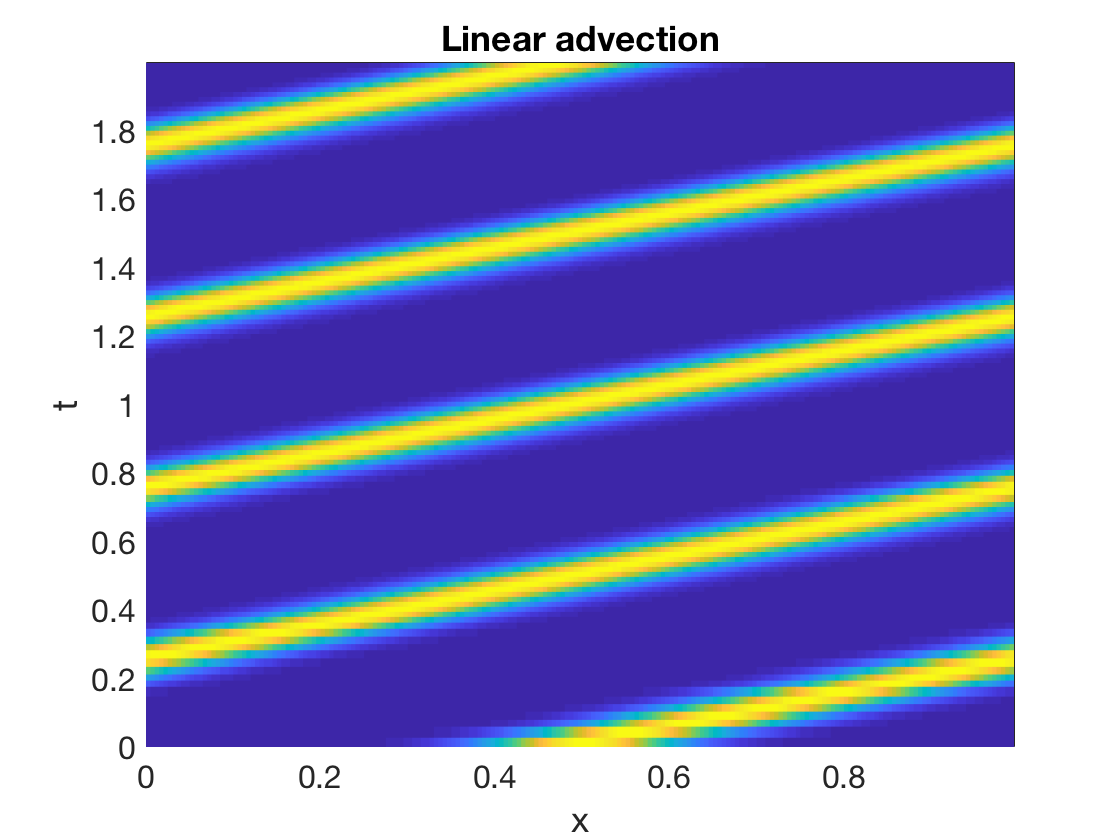

odefun = @(t,u) -c*(Dx*u);
[t,U] = ode113(odefun,[0,2],uinit);
pcolor(x,t(1:10:end),U(1:10:end,:))
shading flat,  xlabel('x'),  ylabel('t')    % ignore this line
title('Linear advection')    % ignore this line

You can see the hump traveling rightward at constant speed, traversing the domain once for each integer multiple of $t=1/2$. We note the average time step that was chosen:

avgtau1 = mean(diff(t))

avgtau1 =        1/646   


We cut $h$ by a factor of two and solve again.

[x,Dx] = diffper(400,[0 1]);
c = 2;  
uinit = exp(-80*(x-0.5).^2);
odefun = @(t,u) -c*(Dx*u);
[t,U] = ode113(odefun,[0,2],uinit);

The CFL condition suggests that the time step should be cut by a factor of two also.

avgtau2 = mean(diff(t))

avgtau2 =        1/1355  


ratio = avgtau1 / avgtau2

ratio =     1355/646   
